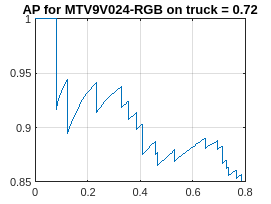

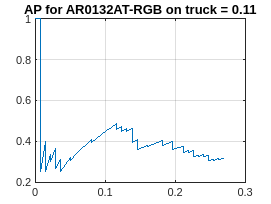

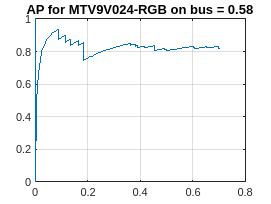

No match in image: 1112203610


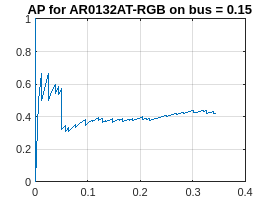

No match in image: 1113184752
No match in image: 1113185530


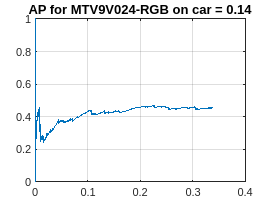

No match in image: 1113184752
No match in image: 1113185530


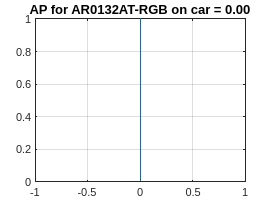

No match in image: 1112175152
No match in image: 1112180533
No match in image: 1113040745
No match in image: 1113040816
No match in image: 1113041841
No match in image: 1113044513
No match in image: 1113183118
No match in image: 1113234756
No match in image: 1114025303
No match in image: 1114030326


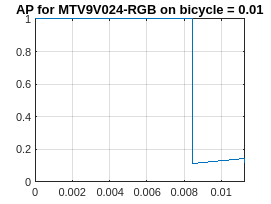

No match in image: 1112175152
No match in image: 1112180533
No match in image: 1113040745
No match in image: 1113040816
No match in image: 1113041841
No match in image: 1113044513
No match in image: 1113234756
No match in image: 1114025303
No match in image: 1114030326


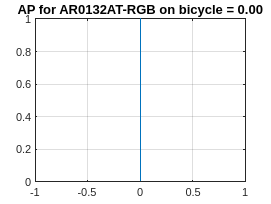

No match in image: 1112173157
No match in image: 1112183100
No match in image: 1113041313
No match in image: 1113181953
No match in image: 1113182930
No match in image: 1113230637
No match in image: 1114000532
No match in image: 1114012235
No match in image: 1114093206
No match in image: 1114103619


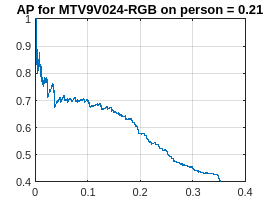

No match in image: 1113041313
No match in image: 1113230637
No match in image: 1114000532
No match in image: 1114012235
No match in image: 1114093206


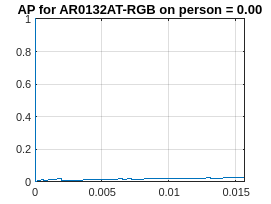

% Demonstration of how to use our database of images to
% evaluate the effectiveness of two sensors for detecting
% a specific class of closest object

% D. Cardinal, Stanford University, 2023

% First we get a collection of images from our database that
% have a specific class of object as the closest:

% Get a collection of images with a specific class of closest target
ourDB = isetdb();
dbTable = 'sensorImages';
filter = 'closestTarget.label';
targetClasses = {'truck', 'bus', 'car', 'bicycle' 'person'};
% targetClasses = {'person'};
% Currently these are the two automotive sensors we have in our database
%sensorNames = {'MTV9V024-RGB'};
sensorNames = {'MTV9V024-RGB', 'AR0132AT-RGB'};

% We can limit our results to a specific scanerio
singleScenario = 'daytime_20_500';
for jj = 1:numel(targetClasses)
    if ~isempty(singleScenario)
        queryString = sprintf("{""closestTarget.label"": ""%s"", ""scenario"":""%s""}", ...
            targetClasses{jj}, singleScenario);
    else
        queryString = sprintf("{""closestTarget.label"": ""%s""}", targetClasses{jj});
    end
    sensorImages = ourDB.docFind(dbTable, queryString);

    % Separate images by sensor
    perSensorImages = {};
    perSensorResults = {};

    for ii = 1:numel(sensorNames)
        perSensorIndex = arrayfun(@(x) matches(x.sensorname, sensorNames{ii}),sensorImages);
        perSensorImages{ii} = sensorImages(perSensorIndex); %#ok<*SAGROW>

        % prune for degugging
        [ap, precision, recall] = ol_apCompute(perSensorImages{ii}, 'class', targetClasses{jj});
        perSensorResults{ii} = {ap, precision, recall};

        figure;
        plot(recall, precision);
        grid on
        title(sprintf('AP for %s on %s = %.2f', sensorNames{ii}, targetClasses{jj}, ap))

    end
end